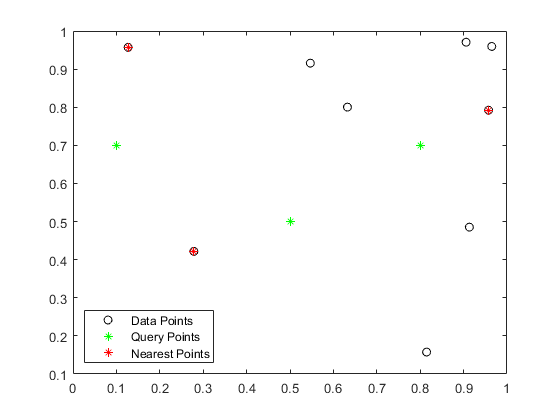

rng default;
P = rand([10 2]);
PQ = [0.5 0.5; 0.1 0.7; 0.8 0.7];
[k,dist] = dsearchn(P,PQ);

plot(P(:,1),P(:,2),'ko')
hold on
plot(PQ(:,1),PQ(:,2),'*g')
hold on
plot(P(k,1),P(k,2),'*r')
legend('Data Points','Query Points','Nearest Points','Location','sw')

## 读取矢量文件

clc;
clear all;
% 读取线数据
name = 'E:\10_DataFile\zero_watermarking_data\exprient_data\jiangsu_polyline_ne10_sim_prj.shp';
shape_datas = shaperead(name);
shape_counts = length(shape_datas);

% 记录各个图形的中心点
feature_center = [];
feature_area = [];

% 计算线数据各要素的最小外接矩形中心点
for shape_current = 1:1:shape_counts
    % 获取当前要素
    shape_data = shape_datas(shape_current);
    % 获取单个要素的X坐标集合,去除最后的NaN值
    coords_x = shape_data.X(~isnan(shape_data.X));
    % 获取单个要素的Y坐标集合,去除最后的NaN值
    coords_y = shape_data.Y(~isnan(shape_data.Y));
    
    % 计算要素面积
    shape_area = polyarea(coords_x,coords_y);
    
    % 获取构建最小外接矩形的索引
    [rectx,recty,~,~,index,~,~] = minboundrect(coords_x,coords_y,'a');
    % 获取外接矩形中心点
    count_rect = length(rectx) - 1;
    rectx = rectx(1:count_rect);
    recty = recty(1:count_rect);
    dx = mean(rectx);
    dy = mean(recty);
    
    % 保存数据中心点和面积，用作后续实验
    feature_center = [feature_center;dx,dy];
    feature_area = [feature_area;shape_area];    
end

% 将中心点和面积数据导出
index_strC = strfind(name,'\');
namepath = name(1:index_strC(end));
txt_path = strcat(namepath,'center_area.txt');

fid=fopen(txt_path,'wt'); 
fprintf(fid,'%f ',feature_center,feature_area); 
fclose(fid);  %关闭文件；

%% 计算检索每个点的最近邻点
% 设置判断标准
kdtreeobj = KDTreeSearcher(feature_center,'distance','euclidean');
% 最近邻点个数
K  =  10;

feature_center_first = [];
feature_center_second = [];
% 最近邻检索，第一个参数是被检索数据，第二个参数是检索数据
[idx,dist]=knnsearch(feature_center,feature_center,'dist','euclidean','k',K);

% 检索每一个点，判断每个点与最近相邻十个点的拓扑关系
count_points = length(feature_center);
% 检索每一个点
for i = 1:1:count_points
    % 获取当前点的坐标，用于判断相交
    shape_data_current = shape_datas(idx(j));
    % 获取单个要素的X坐标集合,去除最后的NaN值
    coords_x_current = shape_data_current.X(~isnan(shape_data.X));
    % 获取单个要素的Y坐标集合,去除最后的NaN值
    coords_y_current = shape_data_current.Y(~isnan(shape_data.Y));
    
    % 记录是否是第一个相离或想交要素
    isfirst_off = 0;
    iffirst_count = 0;
    
    % 检索每一个相邻点
    for j = 1:1:K
        % 获取相应相邻点的坐标
        shape_data_knn = shape_datas(idx(j));
        % 获取单个要素的X坐标集合,去除最后的NaN值
        coords_x_knn = shape_data_knn.X(~isnan(shape_data.X));
        % 获取单个要素的Y坐标集合,去除最后的NaN值
        coords_y_knn = shape_data_knn.Y(~isnan(shape_data.Y));
        
        % 计算是否相交
        ifconter = findcounter(coords_x_current,coords_y_current,coords_x_knn,coords_y_knn);
        if ifconter==1 && iffirst_count==0
            % 若相交则计算相交面积，并记录相交面积和相应索引
            iffirst_count = 1;
            
        elseif ifconter==0 && isfirst_off==0
            % 找到第一个相离要素，计算面积，并记录索引
            % 计算两个要素距离最近的点
            isfirst_off = 1;
            
        end
    end
    
end



clf;
clc;
clear all;
% 测试各种函数
p = [0,0;1,1;1,0]

p =      0     0
     1     1
     1     0


xa = p(:,1)

xa =      0
     1
     1


ya = p(:,2)

ya =      0
     1
     0


polyarea(p(:,1),p(:,2))

ans = 0.5000


%% 随机生成两个多边形
x1=rand(1,4);
y1=rand(1,4);
Px=[x1,x1(1)];
Py=[y1,y1(1)];
figure(1)
clf
ang=cart2pol((x1-mean(x1)),(y1-mean(y1)));
[sortang,sortindex]=sort(ang);
sx1=x1(sortindex);
sy1=y1(sortindex);
Sx1=[sx1,sx1(1)];
Sy1=[sy1,sy1(1)];
plot(Sx1,Sy1,'--')
hold on
x2=rand(1,4);
y2=rand(1,4);
ang=cart2pol((x2-mean(x2)),(y2-mean(y2)));
[sortang,sortindex]=sort(ang);
sx2=x2(sortindex);
sy2=y2(sortindex);
Sx2=[sx2,sx2(1)];
Sy2=[sy2,sy2(1)];
plot(Sx2,Sy2,'g-')

% 判断是否相交
ifconter = findcounter(Sx1,Sy1,Sx2,Sy2)

ifconter = 1

% 判断哪些点在面内
[in_p,out_p] = inpolygon(1,1,Sx2,Sy2)

in_p = logical
   0


out_p = logical
   0


% 将坐标转化为面
p1 = polyshape(Sx1,Sy1);
p2= polyshape(Sx2,Sy2);
% 第一个输出参数为交点坐标，第二个参数为该相交点属于哪个要素，第三个参数为该相交点属于第几个点
[a,b,c] = intersect(p1,p2)

a =   polyshape - 属性:

      Vertices: [6×2 double]
    NumRegions: 1
      NumHoles: 0


b =      0
     0
     0
     0
     0
     0


c =      0
     0
     0
     0
     0
     0


point_1 = [a.Vertices(:,1),a.Vertices(:,2)]

point_1 =     0.3170    0.0909
    0.1959    0.2266
    0.6067    0.4366
    0.6631    0.4366
    0.7362    0.3703
    0.7627    0.1785


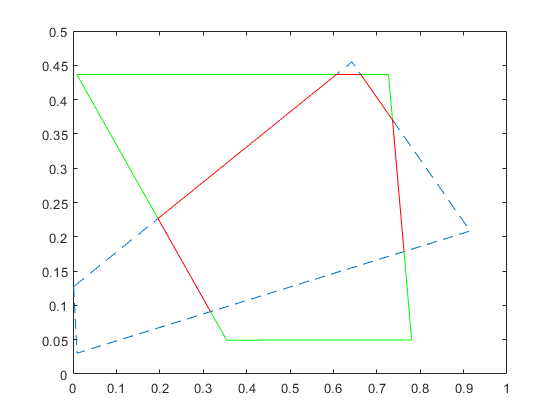


hold on
plot(point_1(:,1),point_1(:,2),'r-')

polyarea(point_1(:,1),point_1(:,2))

ans = 0.1183

% 二维K个最近点检索
P = rand([10 2])

P =     0.2428    0.4257
    0.9174    0.6444
    0.2691    0.6476
    0.7655    0.6790
    0.1887    0.6358
    0.2875    0.9452
    0.0911    0.2089
    0.5762    0.7093
    0.6834    0.2362
    0.5466    0.1194


PQ = [0.5 0.5;0.1 0.7]

PQ =     0.5000    0.5000
    0.1000    0.7000


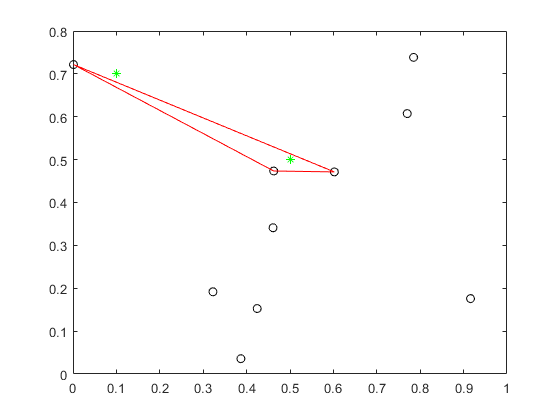



K = 2;

hold off

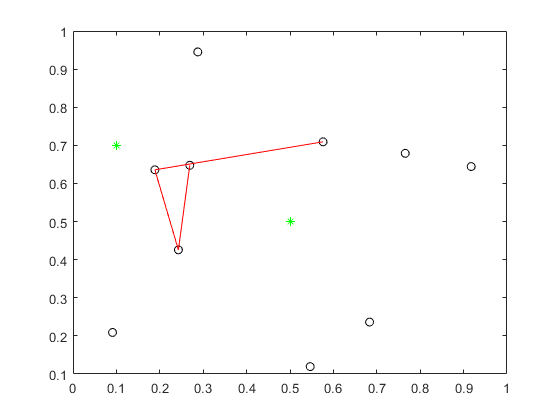

plot(P(:,1),P(:,2),'ko')
hold on
plot(PQ(:,1),PQ(:,2),'*g')

% 设置判断标准
kdtreeobj = KDTreeSearcher(P,'distance','euclidean');
% 检索每个点的10个最近邻点
[idx,dist]=knnsearch(P,PQ,'dist','euclidean','k',2);

%[indices,dists] = findNearestNeighbors(P,PQ,K);


%显示近邻点
points=[];
for i=1:1:2
    id=idx(1,i);
    points=[points;P(id,1),P(id,2)];
    id=idx(2,i);
    points=[points;P(id,1),P(id,2)];
end

% points=[P(4,1),P(4,2);P(5,1),P(5,2);P(6,1),P(6,2);P(8,1),P(8,2)];


hold on
plot(points(:,1),points(:,2),'red')

% [in_p,out_p] = inpolygon(1,1,Sx2,Sy2)
% hold off
% polyarea([0,0,1,1],[0,1,1,0])
% plot([0,0,1,1],[0,1,1,0],'red')
% clf

clf;
x = [0,0,1,0.5,1]';
y = [0,1,1,1,0]';

x2 = [2,2,3,3]';
y2 = [0,1,1,0]';

points1 = struct('x',x,'y',y);
points2 = struct('x',x2,'y',y2);

% min_d = min_dist_between_two_polygons(points1,points2,1)

P = [1,1]';
Q1=[0,0]';
Q2=[0,1]';

    % P-点坐标；Q1, Q2线上两点坐标
    d = abs(det([Q2-Q1,P-Q1]))/norm(Q2-Q1)

d = 1

function ifconter = findcounter(P1X,P1Y,P2X,P2Y)
    %% P1X,P1Y,P2X,P2Y分别是两个封闭图形的点
    ifconter=0;
    for i=1:length(P1X)-1
        for j=1:length(P2X)-1
            p1x=P1X(i:i+1)  ;
            p1y= P1Y(i:i+1)  ;
            p2x=P2X(j:j+1);
            p2y=  P2Y(j:j+1);
%             figure(2);
%             clf
%             plot(P1X(i:i+1),P1Y(i:i+1));hold on
%             plot(P2X(j:j+1),P2Y(j:j+1))
            AllX=linspace(min([p1x p2x]),max([p1x p2x]),100);    
            %% 插值
             Int1 = interp1(p1x,p1y,AllX);
             Int2 = interp1(p2x,p2y,AllX);
             intersec=Int1-Int2;
            if(max(intersec)*min(intersec)<0)
                ifconter=1;%有交点 返回1
            end
        end
    end
end